## Kozney - Carman

D1 = 4 / (0.06^0.404 * 0.0425^0.595)

D1 = 81.6198

D2 = 12 / (0.0425^0.404 * 0.02^0.595)

D2 = 440.7571

D3 = 34 / (0.02^0.404 * 0.015^0.595)

D3 = 2.0095e+03

D4 = 50 / (0.015^0.404 * 0.0075^0.595)

D4 = 5.0138e+03


Dave = 100 / (D1 + D2 + D3 + D4)

Dave = 0.0133

SF = 8.4

SF = 8.4000

e = 0.6

e = 0.6000


k = 1.99 * 10^4 * (Dave)^2 * (1/SF^2) * (e^3/(1+e))

k = 0.0067

## Hazen

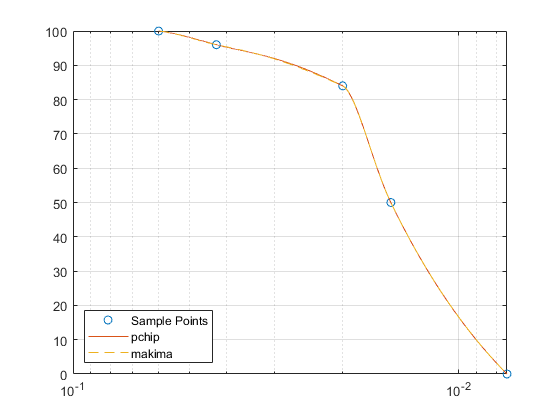

x = [0.06 0.0425 0.02 0.015 0.0075];
y = [100 96 84 50 0];
xq1 = 0:.00001:0.06;
p = pchip(x,y,xq1);
m = makima(x,y,xq1);
semilogx(x,y,'o',xq1,p,'-',xq1,m,'--')
grid on
ax = gca;
ax.XDir = 'reverse';
ylim([0 100])
legend('Sample Points','pchip','makima','Location','southwest')



arrayp = [ transpose(flip(p)), transpose(flip(xq1))];

d10 = 0.09015;
Ch = 1;
compound = Ch  *    1.3;
Hk = compound * d10^2

Hk = 0.0106

## #2

s0 = 8.4 / 0.133

s0 = 63.1579